filepath= "D:\image processing coursera\DL for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification"

filepath = "D:\image processing coursera\DL for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification"

imds= imageDatastore(filepath+"\Train","IncludeSubfolders",true,LabelSource="foldernames" );
[imdsTrain,imdsVal]=splitEachLabel(imds,0.8,"randomized");

imdsTest=imageDatastore(filepath+"\Test","IncludeSubfolders",true,LabelSource="foldernames");
augmented_imdsTest=augmentedImageDatastore([224,224],imdsTest);

augmented_imdsTrain=augmentedImageDatastore([224,224],imdsTrain);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:36        0.001                            3.9852
            1        1       00:00:37        0.001          4.2212                  
           50       17       00:14:30        0.001      0.00066018           0.28109
           90       30       00:26:22        0.001      0.00019709           0.27197
Training stopped: Max epochs completed


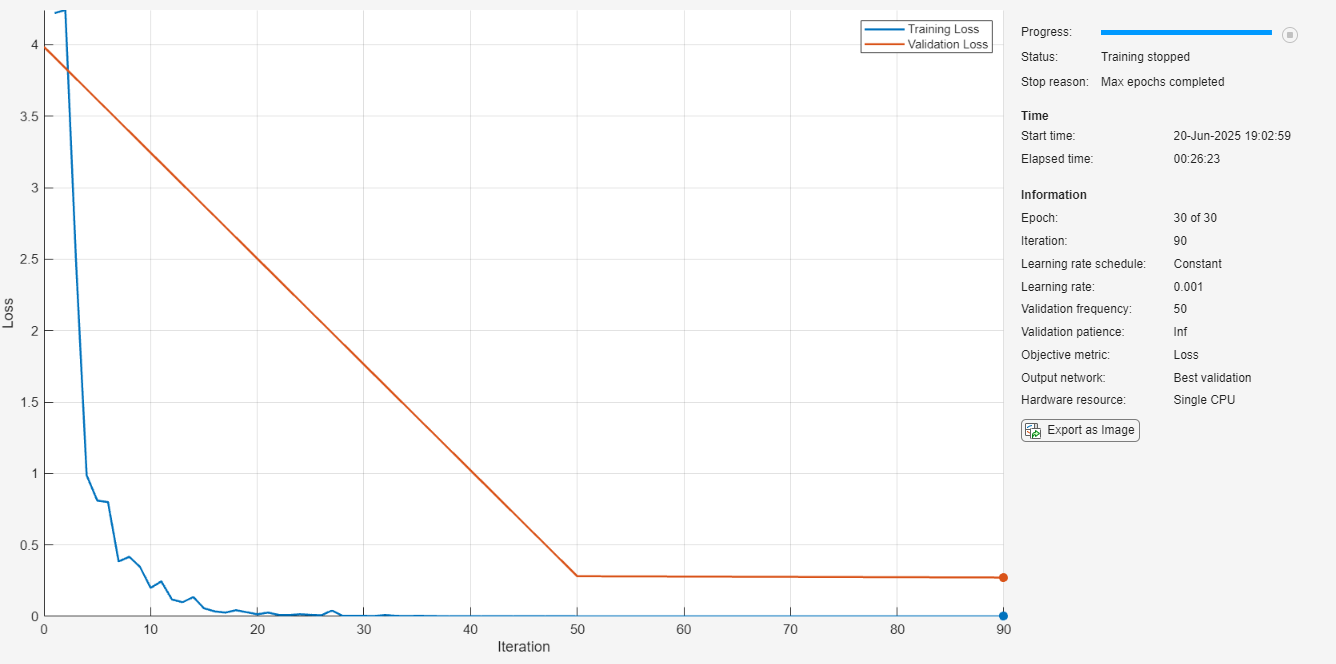

resnet18=imagePretrainedNetwork("resnet18","NumClasses",24);
options= trainingOptions("adam",ValidationData=augmented_imdsTest,Shuffle="every-epoch",Plots="training-progress");
resnet18ASL=trainnet(augmented_imdsTrain,resnet18,"crossentropy",options);

imdsTest=imageDatastore(filepath+"\Test","IncludeSubfolders",true,LabelSource="foldernames");
augmented_imdsTest=augmentedImageDatastore([224,224],imdsTest);
classNames=categories(imdsTest.Labels);
testPreds=minibatchpredict(resnet18ASL,augmented_imdsTest);
testPredClass=scores2label(testPreds,classNames);
TestAccuracy=nnz(testPredClass==imdsTest.Labels)/length(testPredClass);

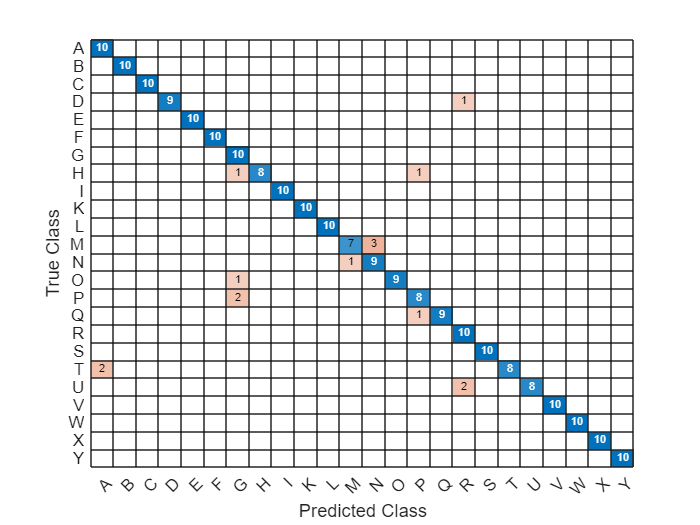

confusionchart(imdsTest.Labels,testPredClass);

testASLmodel(resnet18ASL)

Congratulations on training an accurate model!
Your answer code is: 23061912
